% Problem 1
% See function definition
clear all
Ts = 0.01;
robotpar = [0.26 0.035 0.035];
Rot(pi/3)

ans =     0.5000    0.8660         0
   -0.8660    0.5000         0
         0         0    1.0000


    0.5000         0         0



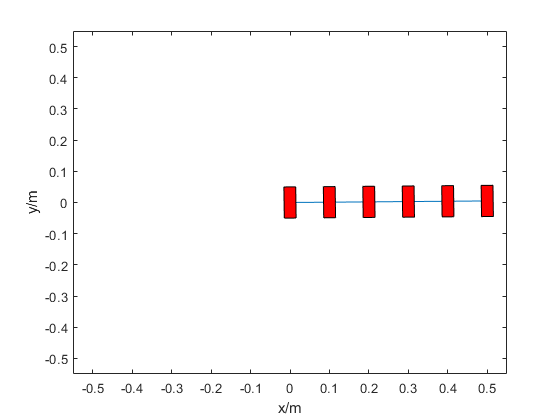

    0.5000    0.5000         0



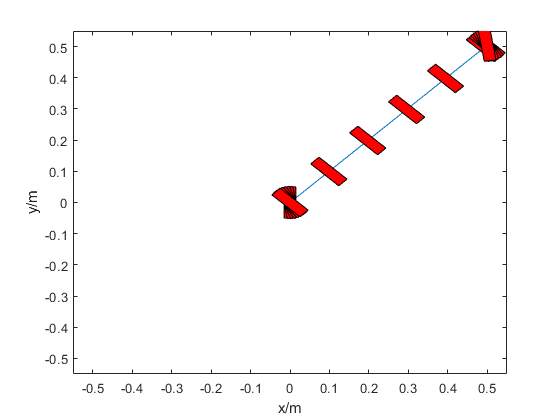

    0.5000   -0.5000   -1.5708



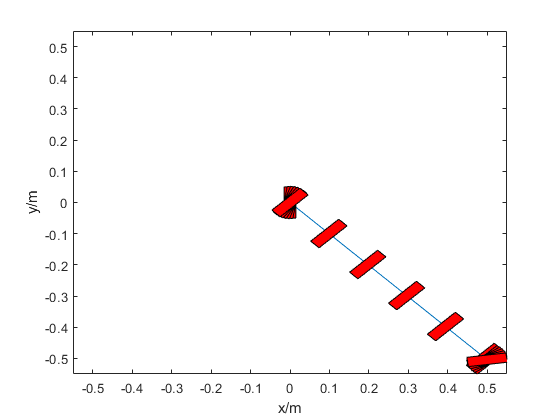

         0    0.5000   -3.1416



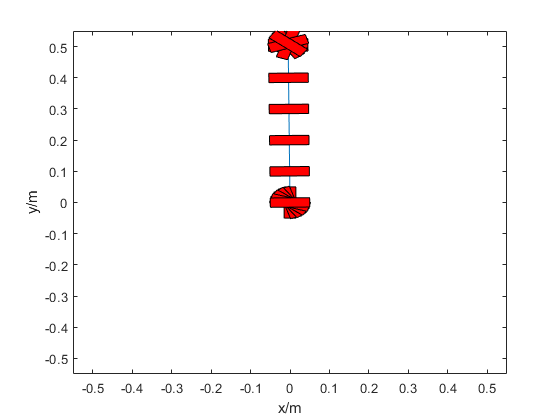

         0         0   -1.5708



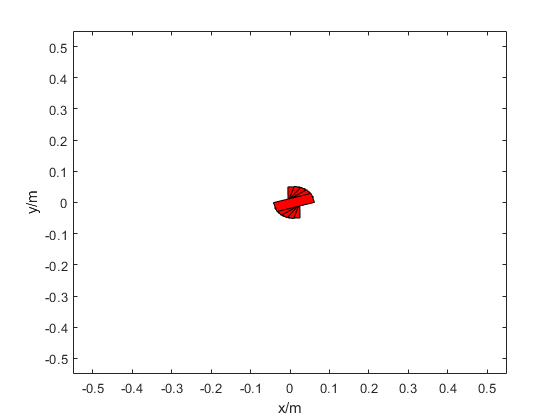

         0   -0.5000         0



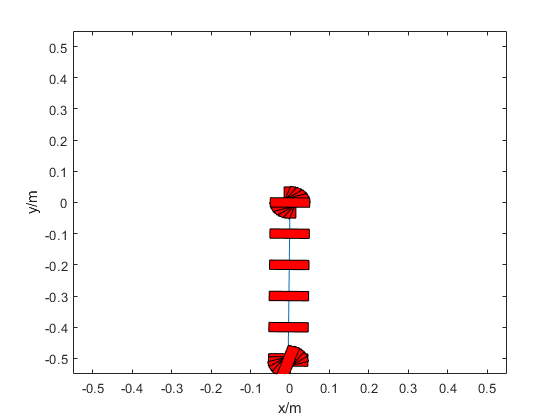

   -0.5000    0.5000         0



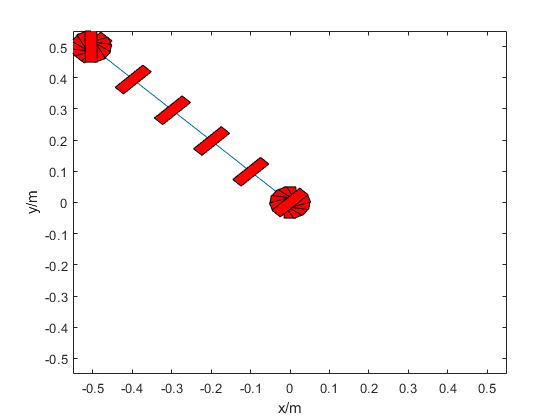

   -0.5000         0         0



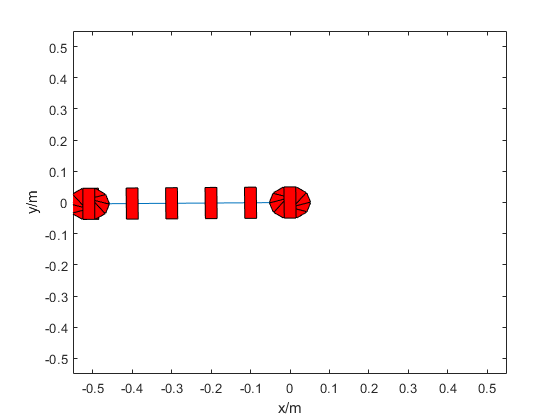

   -0.5000   -0.5000   -3.1416



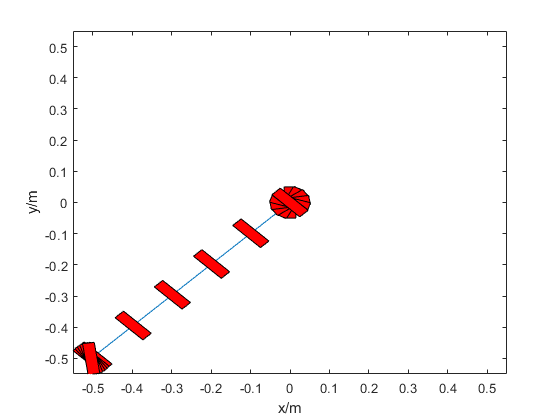

% Problem 2
poses = [0.5 0 0;0.5 0.5 0;0.5 -0.5 -pi/2;0 0.5 -pi;0 0 -pi/2;0 -0.5 0;
    -0.5 0.5 0;-0.5 0 0;-0.5 -0.5 -pi];
pose = [0 0 0];

for i = 1:9
    figure
    grid on
    [hist1, hist2, hist3] = Move(pose, poses(i,:), robotpar,Ts);
    disp(poses(i,:))
    hist = [hist1;hist2;hist3];
    plot(hist(:,1),hist(:,2))
    plot_hist(hist1)
    plot_hist(hist2)
    plot_hist(hist3)
    axis([-0.55 0.55 -0.55 0.55])
    xlabel("x/m")
    ylabel("y/m")
    hold off
end

display(length(hist))

   389



% Problem 3&4, see virtual machine smr-cl files.

function m = Rol_cstr(p) 
    m = [sin(p(1)+p(2)) -cos(p(1)+p(2)) -p(3)*cos(p(2))];
end  
% -----------------------------------------------------------------------------------------------------%
function m = Sld_cstr(p) 
    m = [cos(p(1)+p(2)) sin(p(1)+p(2)) p(3)*sin(p(2))];
end
% -----------------------------------------------------------------------------------------------------%
function m = Rot(theta) 
    m = rotz(-theta);
end
% -----------------------------------------------------------------------------------------------------%
function ws = Cal_ws(theta, speed_I, robotpar)
    radius_l = robotpar(3);
    radius_r = robotpar(2);
    p_left = [pi/2 0 robotpar(1)];
    p_right = [-pi/2 pi robotpar(1)];
    speed_r = Rol_cstr(p_right)*Rot(theta)*speed_I/radius_r; % Right wheel speed
    speed_l = Rol_cstr(p_left)*Rot(theta)*speed_I/radius_l; % Left wheel speed
    ws = [speed_r speed_l];
end
% -----------------------------------------------------------------------------------------------------%
function d = Cal_dis(diff)
    d = sqrt(diff(1)*diff(1)+diff(2)*diff(2));
end
% -----------------------------------------------------------------------------------------------------%
function newpose = kinupdate(pose, robotpar, ts, wheelspeed)
    Rt = Rot(pose(3)); 
    p_left = [pi/2 0 robotpar(1)]; 
    p_right = [-pi/2 pi robotpar(1)]; 
    Cstr = [Rol_cstr(p_left); Rol_cstr(p_right); Sld_cstr(p_left)];
    M = diag([robotpar(3) robotpar(2) 1]);
    v = [wheelspeed(2);wheelspeed(1);0];
    speed_I = inv(Rt)*inv(Cstr)*M*v;  
    newpose = pose + ts*transpose(speed_I);
end
% -----------------------------------------------------------------------------------------------------%
function posehist = forward(dist, speed, pose, robotpar, ts)
    theta = pose(3);
    speed_I = [speed*cos(theta);speed*sin(theta);0];
    wheelspeed = Cal_ws(theta,speed_I,robotpar); 
    if dist < 0                      
        wheelspeed = -wheelspeed;
    end
    posehist = zeros(1,3);
    posehist(1,:) = pose;
    i = 1;
     while true
        N_pose = kinupdate(posehist(i,:), robotpar, ts, wheelspeed);
        posehist(i+1,:) = N_pose;
        diff = N_pose - pose;
        i = i + 1;
        if Cal_dis(diff)>= abs(dist)
            break
        end
     end
end
% -----------------------------------------------------------------------------------------------------%
function posehist = turn(angle, speed, pose, robotpar, ts)
    if angle < 0
        speed = -speed;
    end
    theta_0 = pose(3);
    speed_I = [0;0;speed]; % Only rotation speed
    wheelspeed = Cal_ws(theta_0,speed_I,robotpar); % Initial speed, because θ changes overtime.
    posehist = zeros(1,3); 
    posehist(1,:) = pose;
    i = 1;
    while true
        N_pose = kinupdate(posehist(i,:), robotpar, ts, wheelspeed);
        posehist(i+1,:) = N_pose;
        theta = N_pose(3);
        wheelspeed = Cal_ws(theta,speed_I,robotpar);
        i = i + 1;
        if abs(theta - theta_0)>=abs(angle)
            break
        end
    end
end
%-----------------------------------------Problem 2 ----------------------------------------------------%
function [hist1, hist2, hist3] = Move(pose1, pose2, robotpar,ts)
    diff = pose2 - pose1;
    d_theta = atan2(diff(2),diff(1)) - pose1(3);
    dist = sqrt(diff(1)*diff(1)+diff(2)*diff(2));
    hist1 = turn(d_theta,1,pose1,robotpar,ts); % Turn first
    hist2 = forward(dist,1,hist1(end,:),robotpar,ts); % Go forward 
    t_theta = pose2(3) - atan2(diff(2),diff(1)); % Turn second time
    hist3 = turn(t_theta,1,hist2(end,:),robotpar,ts);
end
%----------------------------------------helpler function------------------------------------------------%
function plot_rectangle(x_coor, y_coor, angle, w, h)
    pos = [x_coor; y_coor];
    pos_1 = [-w/2;- h/2];
    pos_2 = [w/2;-h/2];
    pos_3 = [-w/2;h/2];
    pos_4 = [w/2;h/2];
    pose_1r = rot2(angle)*pos_1 + pos;
    pose_2r = rot2(angle)*pos_2 + pos;
    pose_3r = rot2(angle)*pos_3 + pos;
    pose_4r = rot2(angle)*pos_4 + pos;
    x = [pose_1r(1) pose_2r(1) pose_4r(1) pose_3r(1)];
    y = [pose_1r(2) pose_2r(2) pose_4r(2) pose_3r(2)];
    patch(x, y, 'red')
end

function plot_hist(hist)
    shape = size(hist);
    len = shape(1);
    step = max(5,round(len/5,0));
    if len >= 5
        for i = 1:step:len
        plot_rectangle(hist(i,1),hist(i,2),hist(i,3), 0.03,0.1)
        end
    end
end